# Matriz de paso entre articulaciones

Una vez establecidos los sistemas de coordenadas y medidos los parámetros para cada

una de las articulaciones, se establece que cada transformación entre dos articulaciones

consecutivas (desde la (i-1)-ésima hasta la i-ésima) se puede expresar como una matriz

de transformación.

# 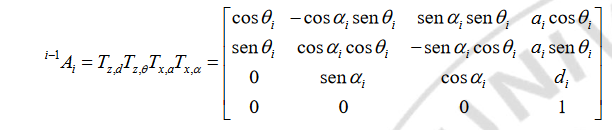

function A = Transformacion_avance(theta, alpha, a, d)
Tzd= rotz(theta);
Tzd(4,4)=1;
Tztheta= eye(4);
Tztheta(3,4)=d;
Txa= eye(4);
Txa (1,4)= a;
Txalpha = rotx(alpha);
Txalpha (4,4) = 1;
A = Tztheta *Tzd *Txa*Txalpha;
end